my_pdf = @(p) modified_gaussian(p,1/2,1/10);
my_cdf = @(p) modified_gaussian_cdf(p,1/2,1/10);
tolerance = 5; % In terms of Basis Points

moneyline_struct = moneyline_solver(my_pdf,my_cdf,tolerance);

if moneyline_struct.matched_answers
    real_profit = moneyline_struct.profit_numerical
else
    profit_numerical = moneyline_struct.profit_numerical
    profit_newton = moneyline_struct.profit_newton
end

real_profit = 0.0567

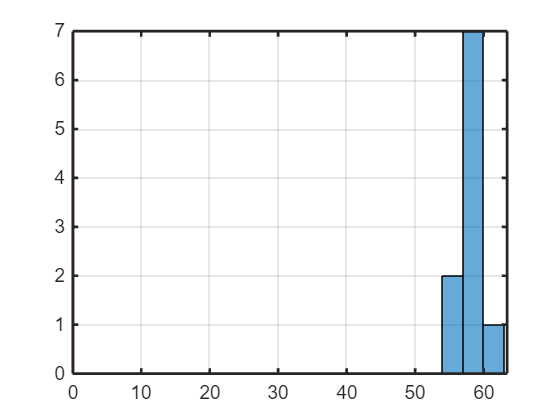


num_trials = 10;
trial_profits = nan(1,num_trials);
for trial_index = 1:num_trials
    sample_values = modified_gaussian_inverse_cdf(rand(1,1e3),.5,.1);
    trial_profits(trial_index) = classical_profit_from_sample(sample_values,ones(1,1e3),tolerance);
end

h = histogram(trial_profits/1e3,'BinWidth',1e-4);
hold on
plot(real_profit*ones(1,2),[0 max(h.BinCounts)])
sexy_plot